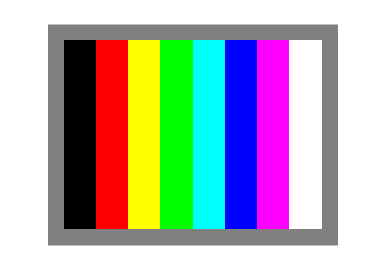

map=[
    128,128,128;
    0,0,0;
    255,0,0;
    255,255,0;
    0,255,0;
    0,255,255;
    0,0,255;
    255,0,255;
    255,255,255
]/255;

imagen = ones(480,630,3)*(128/255);

for i=1:8
    for j=1:3
        imagen(35:445,(35+(70*(i-1))):(105+(70*(i-1))),j) = map(i+1,j);
    end
end
figure
imshow(imagen,map)

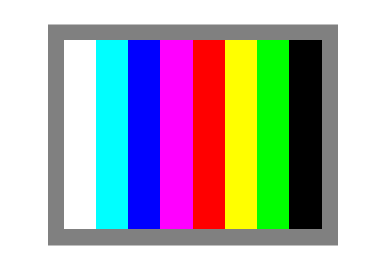


cmy = 1 - map;
for i=1:8
    for j=1:3
        imagen(35:445,(35+(70*(i-1))):(105+(70*(i-1))),j) = cmy(i+1,j);
    end
end
figure
imshow(imagen,cmy)

imagen2 = zeros(1000,1000,3);
map2 = [
    1,0,0;
    0,1,0;
    0,0,1
];

imagen2(1:500,1:500,2)=1;
imagen2(500:1000,500:1000,2)=1;
imagen2(500:1000,1:500,3)=1;
imagen2(1:500,500:1000,1)=1;

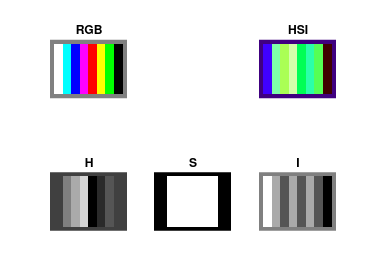

[h,s,i,hsi] = my_hsi(imagen);
hsiMap = hsimap(map);
figure
subplot(2,3,1); imshow(imagen), title("RGB")
subplot(2,3,3); imshow(hsi,hsiMap), title("HSI")
subplot(2,3,4); imshow(h), title("H")
subplot(2,3,5); imshow(s), title("S")
subplot(2,3,6); imshow(i), title("I")

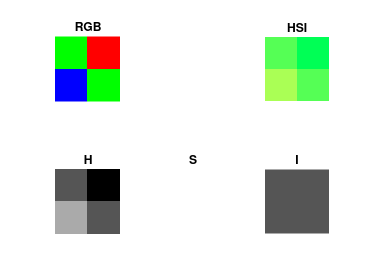

[h,s,i,hsi] = my_hsi(imagen2);
hsiMap = hsimap(map2);
s = padarray(s,[5 5]);
figure
subplot(2,3,1); imshow(imagen2), title("RGB")
subplot(2,3,3); imshow(hsi,hsiMap), title("HSI")
subplot(2,3,4); imshow(h), title("H")
subplot(2,3,5); imshow(s), title("S")
subplot(2,3,6); imshow(i), title("I")

function [HSI] = hsimap(mapa) % funcion para convertir map rgb a hsi
    
    R=mapa(:,1);
    G=mapa(:,2);
    B=mapa(:,3);

    numerador = 0.5*(2*R - G - B);
    denominador = sqrt((R-G).^2 + (R - B).*(G - B));

    zeross = denominador == 0;
    denominador(zeross) = 1;
    numerador(zeross) = 1.5707;

    H = acosd(numerador ./ (denominador)) ;

    I=(R + G + B)./3;
    
    S = zeros(size(R));

    minimo = min(mapa,[],2);
    nozeros = I ~= 0;
    S(nozeros) = 1-minimo(nozeros)./I(nozeros);
    S(~nozeros) = 0;
    H(~nozeros) = 0;

    H(B>G)=360-H(B>G);
    H = real(H)/360;

    HSI=zeros(size(mapa));
    HSI(:,1)=H;
    HSI(:,2)=S;
    HSI(:,3)=I;
end

function [H, S, I, HSI] = my_hsi(imagen) % funcion para convertir imagen rgb a hsi

    img=double(imagen);

    R=img(:,:,1);
    G=img(:,:,2);
    B=img(:,:,3);
    
    numerador = 0.5*(2*R - G - B);
    denominador = sqrt((R-G).^2 + (R - B).*(G - B));
    H = acosd(numerador ./ (denominador + eps)) ;
    
    H(B>G)=360-H(B>G);
    H = H./360;

    I=(R + G + B)/3;
    
    S = zeros(size(R));

    minimo = min(img,[],3);
    nozeros = I ~= 0;
    S(nozeros) = 1-minimo(nozeros)./I(nozeros);
    S(~nozeros) = 0;

    HSI=zeros(size(img));
    HSI(:,:,1)=H;
    HSI(:,:,2)=S;
    HSI(:,:,3)=I;
end 